### Multivariate Pattern Analysis (MVPA) to "decode" de  cognitive process 

#### Alejandro Santos-Mayo, PhD; 2024

Multivariate approaches to neuroimaging data takes the advantage of using the information contained in other points (electrodes, channels or voxels) to extract the neural activity patterns. Instead of using only the information of one source as classical univariate approaches do, MVPA obtain and weight the information of several sources to obtain the pattern within them.

%load condispaceBySubjAvg.mat
%A = cond3acq;
%B = cond5acq;
load DataAB.mat

% Electrode 75 corresponds with Occipital central (Oz)
OccipElec = [65 66 67 68 69 70 72 71 73 74 75 76 77 81 82 83 84 88 89 90 94]

OccipElec =     65    66    67    68    69    70    72    71    73    74    75    76    77    81    82    83    84    88    89    90    94


figure,subplot(3,1,1), plot(mean(mean(A(OccipElec,:,:),1),3), 'r'), hold on, plot(mean(mean(B(OccipElec,:,:),1),3), 'b'), legend('Condtion A', 'Condition B'), ylabel('A/B occipital (mV)')

diffAB_cluster = A(OccipElec,:,:) - B(OccipElec,:,:);
subplot(3,1,2), plot(mean(mean(diffAB_cluster(:,:,:),1),3), 'k'), hold on, plot(zeros(1,size(A,2)),'k', LineWidth=3), legend('Dif A-B'), ylabel('Difference A-B (mV)')

Now, from a univariate perspective, we fit a Student's T-test against 0 using the 51 subjects as distribution.

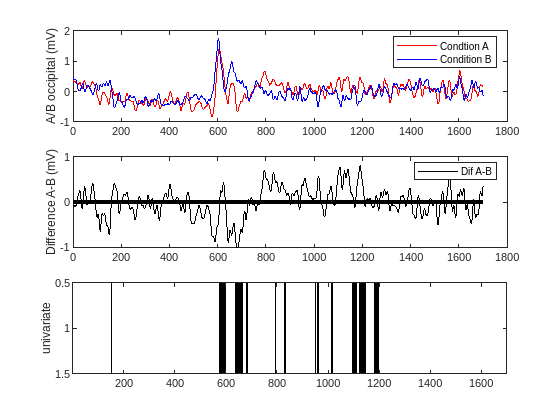

diffAB_univariate = mean(diffAB_cluster,1); % Univariate: 1 elec * 1701 time * 51 subj
h_univariate = ttest(diffAB_univariate, 0, 'tail', 'both', 'Alpha', 0.05, Dim=3); % Ttest in dim 3 => subjects.
subplot(3,1,3),imagesc(h_univariate), colormap([1 1 1; 0 0 0]), ylabel('univariate') % black means statistically significant

Now from a multivariate perspective (specifically here a cross-subject one), we do not mix information of cluster in 1 signal with same weight within them.

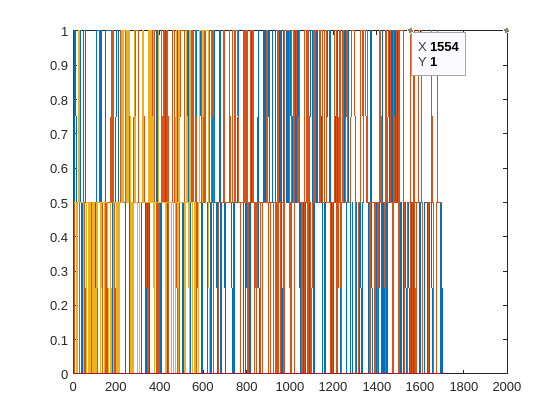

permuted_indices = randperm(51);
%train_indices = permuted_indices(1:40); % 80% of subjects to train classifier.
%test_indices = permuted_indices(41:51); % 20% of subjects to test classifier.
train_indices = permuted_indices(1:50); % 80% of subjects to train classifier.
test_indices = permuted_indices(51); % 20% of subjects to test classifier.

%labels_train = [zeros(40,1); ones(40,1)];
%labels_test = [zeros(11,1); ones(11,1)];
labels_train = [zeros(50,1); ones(50,1)];
labels_test = [zeros(1,1); ones(1,1)];

for time = 1: 1701

    train_matrix = transpose([squeeze(A(OccipElec, time, train_indices)) squeeze(B(OccipElec, time, train_indices))]);
    % train_matrix is 80 subjs (40 A and 40 B) * 21 occipital electrodes.
    obj = fitcsvm(train_matrix,labels_train);
    % We trained supported Vector Machine (SVM) using 80 subjects as observation 
    % and 129 electrodes as features to discriminate.

    test_matrix = transpose([squeeze(A(OccipElec, time, test_indices)) squeeze(B(OccipElec, time, test_indices))]);
    % test_matrix is 22 subjs (11 A and 11 B) * 21 occipital electrodes,
    Yhat = predict( obj, test_matrix ); % gives vector of 0,0,1,1,0,0,1,....etc.
    % We predict the label based on electrodes info,
    
    aha = confusionmat(labels_test,Yhat);
    decoding(time) = sum(diag(aha))./sum(sum(aha)); % Calculate hit rate and store in time-vector.
end

figure, plot(decoding)

This script has provided us a decoding rate (based on hit rate) of the signal for each time step using the informaiton contained along the 21 electrodes. However, the result relies on the permutation and random selection of subjects to train or test groups. We need to repeat it to obtain an increase of the decoding resolution 

clear decoding


for subj = 1:51
%subj
%permuted_indices = randperm(51);
%train_indices = permuted_indices(1:40); % 80% of subjects to train classifier.
%test_indices = permuted_indices(41:51); % 20% of subjects to test classifier.
train_indices = setdiff(1:51,subj); % 80% of subjects to train classifier.
test_indices = subj; % 20% of subjects to test classifier.

%labels_train = [zeros(40,1); ones(40,1)];
%labels_test = [zeros(11,1); ones(11,1)];
labels_train = [zeros(50,1); ones(50,1)];
labels_test = [zeros(1,1); ones(1,1)];

for time = 1: 1701

    train_matrix = transpose([squeeze(A(OccipElec, time, train_indices)) squeeze(B(OccipElec, time, train_indices))]);
    % train_matrix is 80 subjs (40 A and 40 B) * 21 occipital electrodes.
    obj = fitcsvm(train_matrix,labels_train);
    % We trained supported Vector Machine (SVM) using 80 subjects as observation 
    % and 129 electrodes as features to discriminate.

    test_matrix = transpose([squeeze(A(OccipElec, time, test_indices)) squeeze(B(OccipElec, time, test_indices))]);
    % test_matrix is 22 subjs (11 A and 11 B) * 21 occipital electrodes,
    Yhat = predict( obj, test_matrix ); % gives vector of 0,0,1,1,0,0,1,....etc.
    % We predict the label based on electrodes info,
    
    aha = confusionmat(labels_test,Yhat);
    decoding(time,subj) = sum(diag(aha))./sum(sum(aha)); % Calculate hit rate and store in time-vector.
end

end

figure, subplot(2,1,1), plot(mean(decoding,2))

To obtain the statistics, we compute the same Student's T test that computed before to check whether A vs B comparison is different using an univariate or multivariate approach. Since hit rate below 0.5 (chance-level) does not have any meaning, right-tailed T test is computed. We use alpha = 0.25 so that same statistical power is confered here.

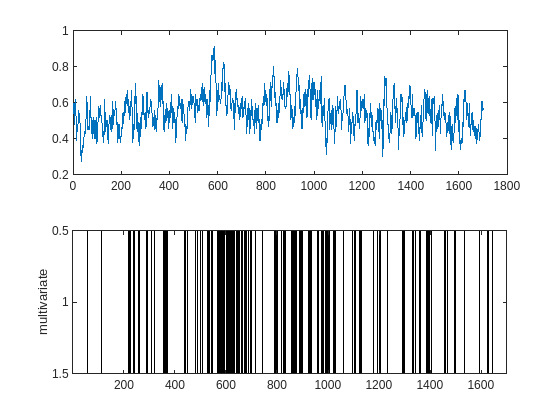

h_multivariate = ttest(decoding, 0.5, 'tail', 'right', 'Alpha', 0.025, Dim=2); % Ttest in dim 3 => subjects.
subplot(2,1,2), imagesc(h_multivariate'), colormap([1 1 1; 0 0 0]), ylabel('multivariate')

Finally, we plot the conditions A and B signal from occipital cluster and the statistically significance from both univariate and multivariate approaches.

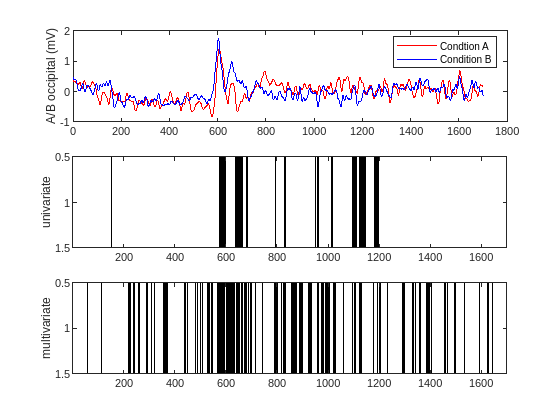

figure
subplot(3,1,1), plot(mean(mean(A(OccipElec,:,:),1),3), 'r'), hold on, plot(mean(mean(B(OccipElec,:,:),1),3), 'b'), legend('Condtion A', 'Condition B'), ylabel('A/B occipital (mV)')
subplot(3,1,2), imagesc(h_univariate), colormap([1 1 1; 0 0 0]), ylabel('univariate')
subplot(3,1,3), imagesc(h_multivariate'), colormap([1 1 1; 0 0 0]), ylabel('multivariate')

#### EXTRA: Check weights in time in univariate and MVPA

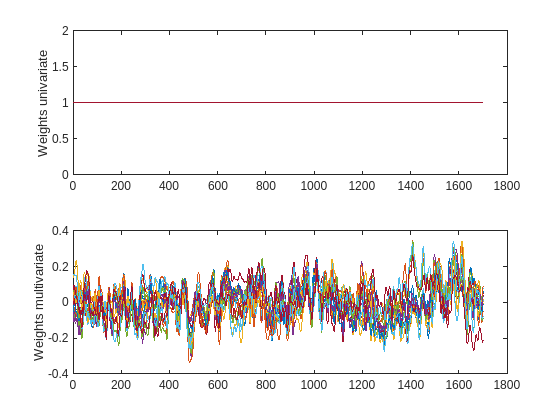


labels_all = [zeros(51,1); ones(51,1)];

for time = 1: 1701
    for elec = 1:21
        all_matrix = transpose([squeeze(A(OccipElec(elec), time, :)) squeeze(B(OccipElec(elec), time, :))]);
        corr = corrcoef(all_matrix, labels_all);
        weights_classifier(time,elec) = corr(1,2);
    end
end

figure, subplot(2,1,1), plot(ones(21,1701)'), ylabel('Weights univariate')
subplot(2,1,2), plot(weights_classifier), ylabel('Weights multivariate')

% %% load data
% 
% 
% % Initializing: Creating ZEROs Mats
% for c = 1:5
%     %for g = 1:5
%         eval(['cond',num2str(c),'acq = zeros([length(chans), 1701, n_subj ]);'])
%         eval(['cond',num2str(c),'hab = zeros([length(chans), 1701, n_subj ]);'])
%     %end
% end
% AvgERP = zeros([129,1701]); % We will use it only for plotting below. Not important
% 
% % Load data and resample
% for s = 1:n_subj
% 
% disp(subjects(s))
% 
% clear outmat
% eval(strcat("load('/mnt/129faeb2-1cd9-413e-87cf-2cbbe75e4011/home/alex/Desktop/Project_DecodingFear/Condispace/Condi_Rawdata/condispas_", num2str(subjects(s)), ".fl40h2.E1.appg.mat')"))
% AvgERP = AvgERP + mean(outmat,3);
% eval(['fid = fopen("/mnt/129faeb2-1cd9-413e-87cf-2cbbe75e4011/home/alex/Desktop/Project_DecodingFear/Condispace/Condi_Rawdata/condispas_', num2str(subjects(s)), '.fl40h2.E1.ig"); '])
% dummy = fgetl(fid);
% indexvectemp = fgetl(fid);
% indexvec = str2num(indexvectemp);
% 
% eval(['dat = importfilecondispas("/mnt/129faeb2-1cd9-413e-87cf-2cbbe75e4011/home/alex/Desktop/Project_DecodingFear/Condispace/condispas_DAT/condispas_', num2str(subjects(s)), '.dat", 1);'])
% conditions = dat.VarName5(1:350);
% csplus = dat.VarName6(1);
% 
% conditionsHab = conditions(indexvec(indexvec<= 150));
% indexVecHab = indexvec(indexvec<= 150);
% conditionsAcq = conditions(indexvec(indexvec > 150));
% indexVecAcq = indexvec(indexvec > 150);
% 
% indxA1 = find(ismember(indexvec, indexVecAcq(conditionsAcq == 1)));
% indxA2 = find(ismember(indexvec, indexVecAcq(conditionsAcq == 2)));
% indxA3 = find(ismember(indexvec, indexVecAcq(conditionsAcq == 3)));
% indxA4 = find(ismember(indexvec, indexVecAcq(conditionsAcq == 4)));
% indxA5 = find(ismember(indexvec, indexVecAcq(conditionsAcq == 5)));
% 
% indxH1 = find(ismember(indexvec, indexVecHab(conditionsHab == 1)));
% indxH2 = find(ismember(indexvec, indexVecHab(conditionsHab == 2)));
% indxH3 = find(ismember(indexvec, indexVecHab(conditionsHab == 3)));
% indxH4 = find(ismember(indexvec, indexVecHab(conditionsHab == 4)));
% indxH5 = find(ismember(indexvec, indexVecHab(conditionsHab == 5)));
% 
% 
% 
% cond1acq(:,:,s) = mean(outmat(:,:,indxA4),3);
% cond2acq(:,:,s) = mean(outmat(:,:,indxA5),3);
% cond3acq(:,:,s) = mean(outmat(:,:,indxA1),3);
% cond4acq(:,:,s) = mean(outmat(:,:,indxA2),3);
% cond5acq(:,:,s) = mean(outmat(:,:,indxA3),3);
% 
% cond1hab(:,:,s) = mean(outmat(:,:,indxH4),3);
% cond2hab(:,:,s) = mean(outmat(:,:,indxH5),3);
% cond3hab(:,:,s) = mean(outmat(:,:,indxH1),3);
% cond4hab(:,:,s) = mean(outmat(:,:,indxH2),3);
% cond5hab(:,:,s) = mean(outmat(:,:,indxH3),3);
% 
% end
% 
% 
% 
% %Now HILBERT
% % [power, phase, complex] = freqtag_HILB(dataset, taggingfreq, filterorder, sensor2plot, plotflag, fsamp)
% % % % % % Hilboutmat = zeros([129, 1701, length(indexvec)]);
% % % % % % for i = 1:length(indexvec)
% % % % % %     fprintf('.')
% % % % % % [power, phase, complex] = freqtag_HILB(outmat(:,:,i), 15, 9, 75, 0, 500);
% % % % % % %[power, phase, complex] = freqtag_HILB(outmat(:,:,i), 15, 1, 75, 0, 500);
% % % % % % Hilboutmat(:,:,i) = power;
% % % % % % end
% % % % % % outmat = Hilboutmat;
% 
% newt = 1; newoutmat = zeros([129, 100, length(outmat(1,1,:))]);
% for tstep = 1:15:1500 % Here we resample data so that GAT are not huge
%     newoutmat(:,newt,:) = (outmat(:,tstep,:) + outmat(:,tstep+1,:) + outmat(:,tstep+2,:) + outmat(:,tstep+3,:) + outmat(:,tstep+4,:) +outmat(:,tstep+5,:) + outmat(:,tstep+6,:) + outmat(:,tstep+7,:) + outmat(:,tstep+8,:) + outmat(:,tstep+9,:) +outmat(:,tstep+10,:) + outmat(:,tstep+11,:) + outmat(:,tstep+12,:) + outmat(:,tstep+13,:) + outmat(:,tstep+14,:) ) ./ 15 ;
%     newt = newt + 1;
% end
% outmat = newoutmat; clear newoutmat
% 
% %%% Order so that the 3 condition is CS+ 2 and 4 NEAR and 1 and 5 FAR
% winTime = 1:100;
% switch csplus
%     case 1
% %         for c = 1:5
% %             eval(['cond', num2str(c),'acq1 = cat(3, outmat(:,winTime,indxA', num2str(c),'), cond', num2str(c),'acq2);'])
% %         end
%         cond1acq = cat(3, outmat(:,winTime,indxA4), cond1acq);
%         cond2acq = cat(3, outmat(:,winTime,indxA5), cond2acq);
%         cond3acq = cat(3, outmat(:,winTime,indxA1), cond3acq);
%         cond4acq = cat(3, outmat(:,winTime,indxA2), cond4acq);
%         cond5acq = cat(3, outmat(:,winTime,indxA3), cond5acq);
%         cond1hab = cat(3, outmat(:,winTime,indxH4), cond1hab);
%         cond2hab = cat(3, outmat(:,winTime,indxH5), cond2hab);
%         cond3hab = cat(3, outmat(:,winTime,indxH1), cond3hab);
%         cond4hab = cat(3, outmat(:,winTime,indxH2), cond4hab);
%         cond5hab = cat(3, outmat(:,winTime,indxH3), cond5hab);
%     case 2
%         cond1acq = cat(3, outmat(:,winTime,indxA5), cond1acq);
%         cond2acq = cat(3, outmat(:,winTime,indxA1), cond2acq);
%         cond3acq = cat(3, outmat(:,winTime,indxA2), cond3acq);
%         cond4acq = cat(3, outmat(:,winTime,indxA3), cond4acq);
%         cond5acq = cat(3, outmat(:,winTime,indxA4), cond5acq);
%         cond1hab = cat(3, outmat(:,winTime,indxH5), cond1hab);
%         cond2hab = cat(3, outmat(:,winTime,indxH1), cond2hab);
%         cond3hab = cat(3, outmat(:,winTime,indxH2), cond3hab);
%         cond4hab = cat(3, outmat(:,winTime,indxH3), cond4hab);
%         cond5hab = cat(3, outmat(:,winTime,indxH4), cond5hab);
%     case 3
%         cond1acq = cat(3, outmat(:,winTime,indxA1), cond1acq);
%         cond2acq = cat(3, outmat(:,winTime,indxA2), cond2acq);
%         cond3acq = cat(3, outmat(:,winTime,indxA3), cond3acq);
%         cond4acq = cat(3, outmat(:,winTime,indxA4), cond4acq);
%         cond5acq = cat(3, outmat(:,winTime,indxA5), cond5acq);
%         cond1hab = cat(3, outmat(:,winTime,indxH1), cond1hab);
%         cond2hab = cat(3, outmat(:,winTime,indxH2), cond2hab);
%         cond3hab = cat(3, outmat(:,winTime,indxH3), cond3hab);
%         cond4hab = cat(3, outmat(:,winTime,indxH4), cond4hab);
%         cond5hab = cat(3, outmat(:,winTime,indxH5), cond5hab);
%     case 4
%         cond1acq = cat(3, outmat(:,winTime,indxA2), cond1acq);
%         cond2acq = cat(3, outmat(:,winTime,indxA3), cond2acq);
%         cond3acq = cat(3, outmat(:,winTime,indxA4), cond3acq);
%         cond4acq = cat(3, outmat(:,winTime,indxA5), cond4acq);
%         cond5acq = cat(3, outmat(:,winTime,indxA1), cond5acq);
%         cond1hab = cat(3, outmat(:,winTime,indxH2), cond1hab);
%         cond2hab = cat(3, outmat(:,winTime,indxH3), cond2hab);
%         cond3hab = cat(3, outmat(:,winTime,indxH4), cond3hab);
%         cond4hab = cat(3, outmat(:,winTime,indxH5), cond4hab);
%         cond5hab = cat(3, outmat(:,winTime,indxH1), cond5hab);
%     case 5
%         cond1acq = cat(3, outmat(:,winTime,indxA3), cond1acq);
%         cond2acq = cat(3, outmat(:,winTime,indxA4), cond2acq);
%         cond3acq = cat(3, outmat(:,winTime,indxA5), cond3acq);
%         cond4acq = cat(3, outmat(:,winTime,indxA1), cond4acq);
%         cond5acq = cat(3, outmat(:,winTime,indxA2), cond5acq);
%         cond1hab = cat(3, outmat(:,winTime,indxH3), cond1hab);
%         cond2hab = cat(3, outmat(:,winTime,indxH4), cond2hab);
%         cond3hab = cat(3, outmat(:,winTime,indxH5), cond3hab);
%         cond4hab = cat(3, outmat(:,winTime,indxH1), cond4hab);
%         cond5hab = cat(3, outmat(:,winTime,indxH2), cond5hab);
% end
% 
% end